# Лабораторная работа №2

Метод наименьших квадратов.

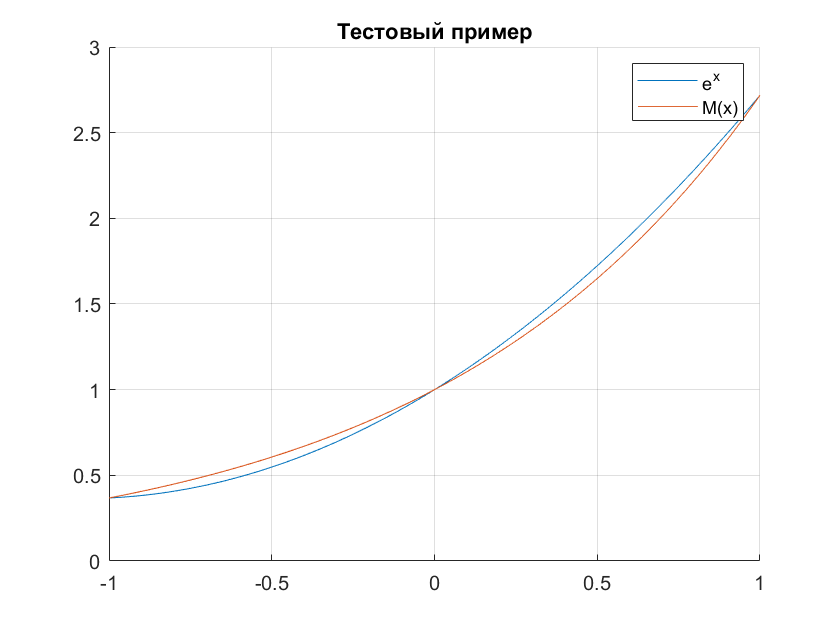

n_max = 3;
 
f = @(x) exp(x);
x = linspace(-1, 1, n_max);
x0 = linspace(-1, 1, 100);
y = f(x);
y0 = mnk(x, y, x0, n_max-1);
figure
hold on
plot(x0, y0)
fplot(f, [-1, 1])
grid on
legend('e^x', 'M(x)')
title("Тестовый пример")

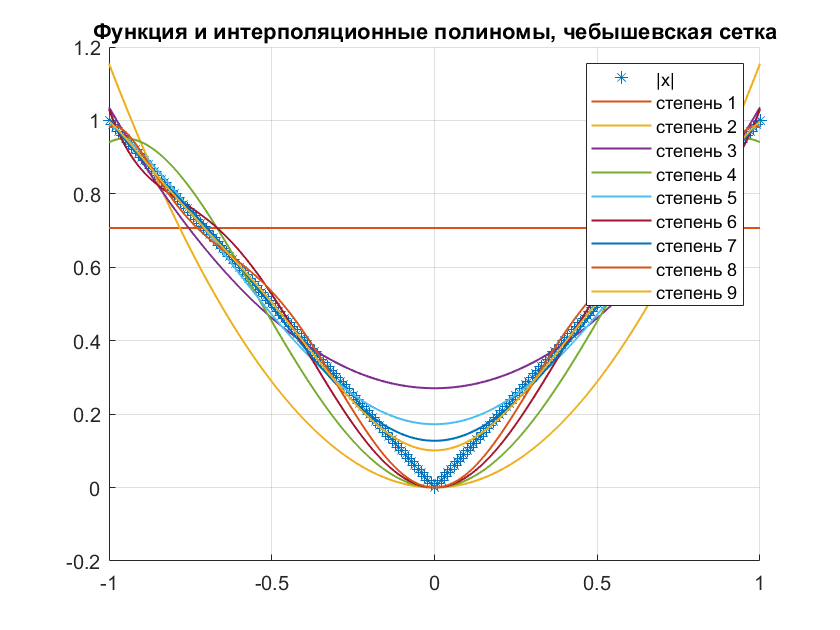

figure
hold on
grid on
xx = -1:0.01:1;
plot(xx, abs(xx), '*');
str = '|x|';
for i = 2:10
%     x = linspace(-1, 1, i);
    x = get_cheby_points([-1, 1], i);
    y = abs(x);
    xx = -1:0.01:1;
    yy = mnk(x, y, xx, i-1);
    plot(xx, yy, 'LineWidth', 1);
    str = [str, "степень " + num2str(i-1)];
end
legend(str);
title("Функция и интерполяционные полиномы, чебышевская сетка")

% title("Функция и интерполяционные полиномы, равномерная сетка")

Построение зависимости погрешности от количества узлов.

Eall = []


Eall =

     []



f = function_handle with value:
    @(x)exp(-x)


Analyzing and transferring files to the workers ...done.


Равномерная сетка, непрерывная функция


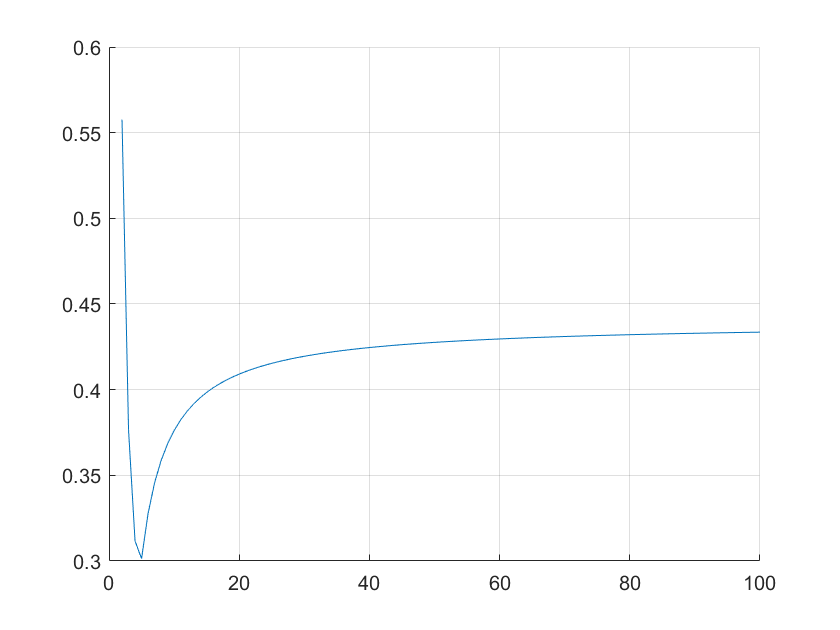

f = function_handle with value:
    @(x)exp(-x)


Равномерная сетка, непрерывная функция


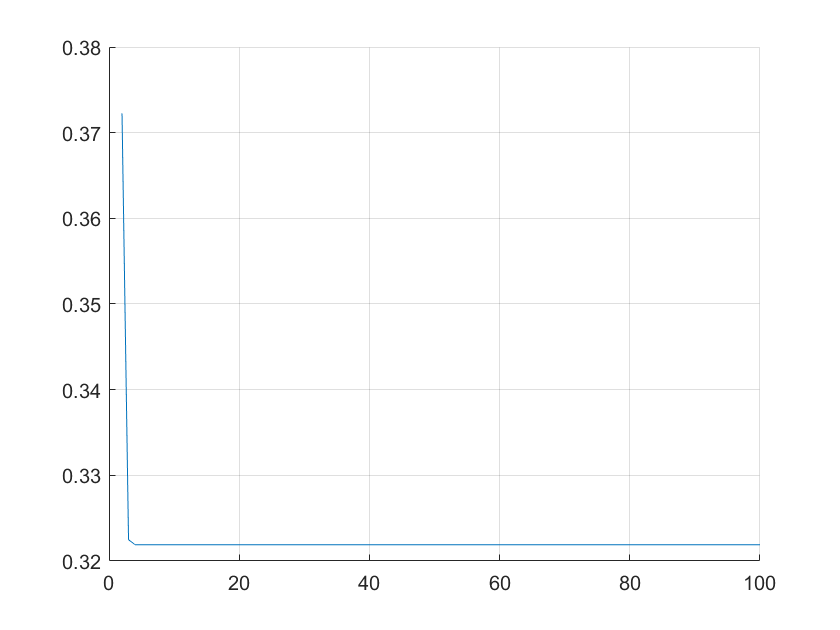

f = function_handle with value:
    @(x)abs(x)


Равномерная сетка, непрерывная функция


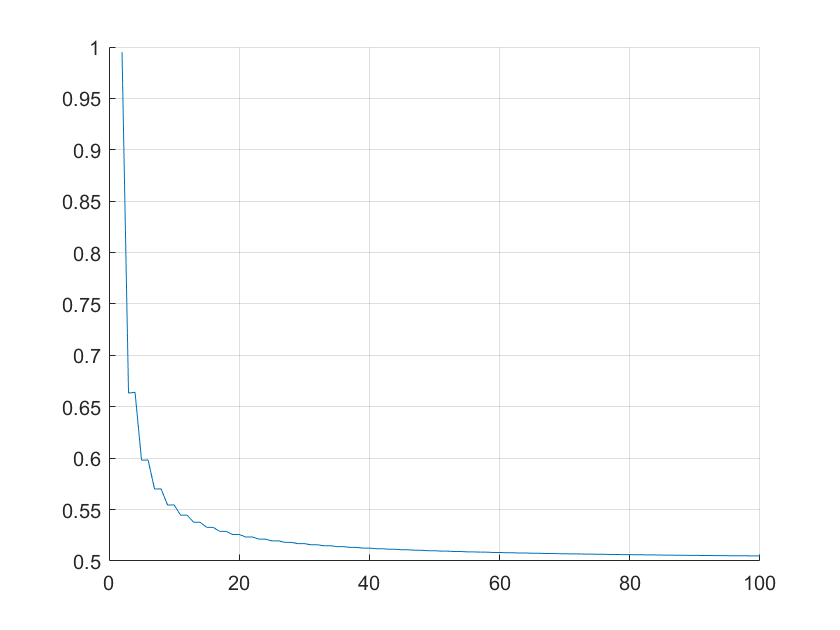

f = function_handle with value:
    @(x)abs(x)


Равномерная сетка, непрерывная функция


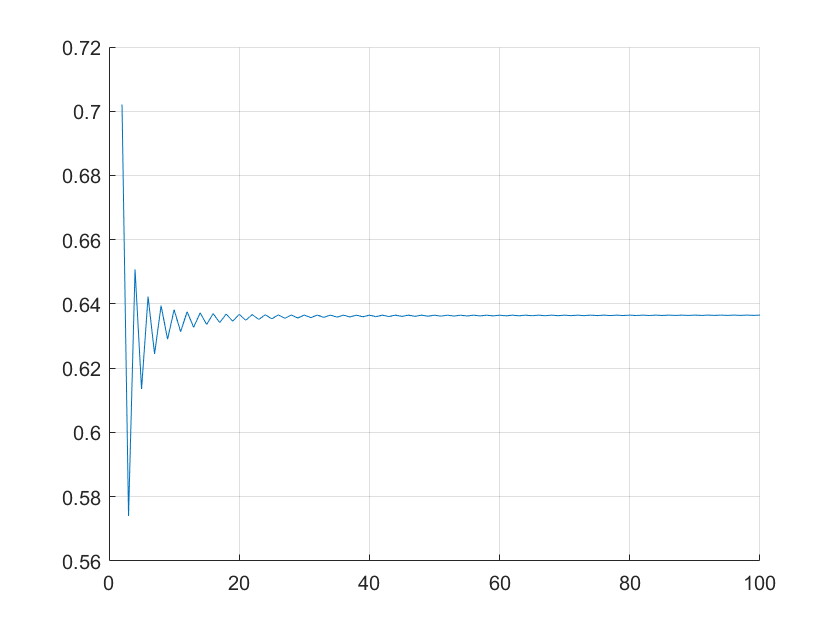

for i = 1:4
    n_max = 100;
     
    if mod(i, 2) == 1
        type = "rvn";
    else
        type = "cheby";
    end
    if i > 2
        f = @(x) abs(x)
    else
        f = @(x) exp(-x)
    end
    E = [];
    parfor n = 2:n_max
        E(n) = get_err_cont(f, [-1, 1], n, type, n-1);
    end
    disp('Равномерная сетка, непрерывная функция');
    figure
    hold on
    grid on
    loglog(2:n_max, E(2:end));
    Eall = [Eall; E];
end

Eall = []


Eall =

     []



for i = 1:4
    n_max = 500;
     
    if mod(i, 2) == 1
        type = "rvn";
    else
        type = "cheby";
    end
    if i > 2
        f = @(x) abs(x)
    else
        f = @(x) exp(-x)
    end
    E = [];
    parfor n = 1:n_max-1
        E(n) = get_err_cont(f, [-1, 1], n_max, type, n);
    end
    disp('Равномерная сетка, непрерывная функция');
    Eall = [Eall; E];
end

f = function_handle with value:
    @(x)exp(-x)


> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 133)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 133)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 133)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFun

Равномерная сетка, непрерывная функция


f = function_handle with value:
    @(x)exp(-x)


> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 142)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 142)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 142)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFun

Равномерная сетка, непрерывная функция


f = function_handle with value:
    @(x)abs(x)


> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 133)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 133)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 133)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFun

Равномерная сетка, непрерывная функция


f = function_handle with value:
    @(x)abs(x)


> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 142)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 142)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFunction (line 46)

> In LiveEditorEvaluationHelperE1501152458>mnk (line 111)
  In LiveEditorEvaluationHelperE1501152458>get_err_cont (line 142)
  In parallel_function>make_general_channel/channel_general (line 837)
  In remoteParallelFun

Равномерная сетка, непрерывная функция


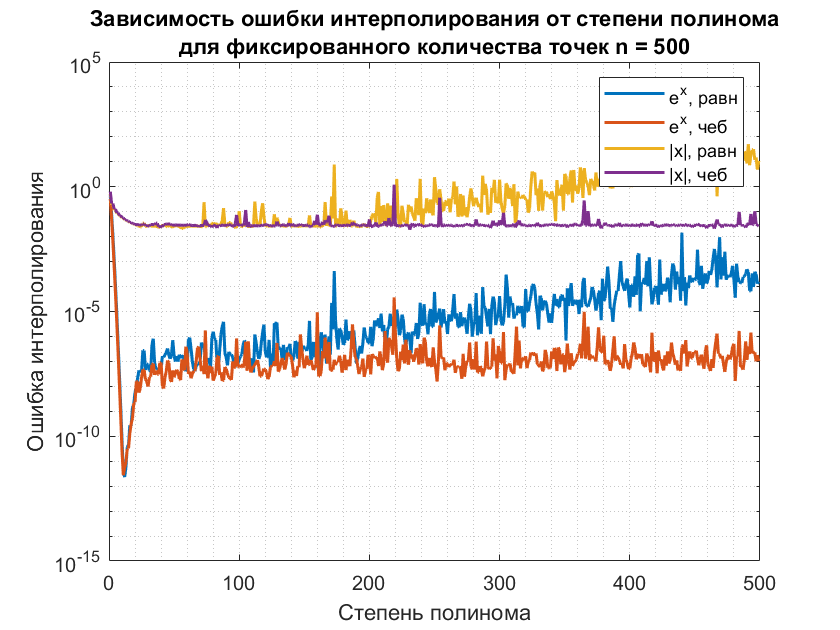

figure
semilogy(1:n_max-1, Eall(1, :), 'LineWidth', 1.5)
hold on;
semilogy(1:n_max-1, Eall(2, :), 'LineWidth', 1.5)
semilogy(1:n_max-1, Eall(3, :), 'LineWidth', 1.5)
semilogy(1:n_max-1, Eall(4, :), 'LineWidth', 1.5)
grid minor
xlabel("Степень полинома")
ylabel("Ошибка интерполирования")
title({"Зависимость ошибки интерполирования от степени полинома"; "для фиксированного количества точек n = " + num2str(n_max)})
legend("e^x, равн", "e^x, чеб", "|x|, равн", "|x|, чеб")

function y0 = mnk(x, y, x0, k)
    y0 = zeros(size(x0));
    A = zeros(k+1);
    for i = 1:k+1
        for j = 1:k+1
            if i == j
                A(i, j) = sum(x.^(2*(i-1)));
            else
                A(i, j) = sum(x.^(i+j-2));
            end
        end
    end
    A(1, 1) = max(size(x));
    B = zeros([k+1, 1]);
    for i = 1:k+1
        c = 0;
        for j = 1:max(size(x))
           c = c + x(j)^(i-1)*y(j);
        end
        B(i) = c;
    end
    th = A \ B;
    for i = 1:max(size(x0))
        c = 0;
        for j = 2:size(th)
            c = c + th(j)*x0(i)^(j-1);
        end
       y0(i) =  th(1) + c;
    end
end

function delta = get_error(x_tr, x_pred)
    a = x_tr' - x_pred';
    a = abs(a);
    delta = max(a);
end

function eps = get_err_cont(f, dd, n, type_s, k)
    if type_s == "rvn"
        X = linspace(dd(1), dd(2), n);
        Y = f(X);
        xx = [];
        xx = linspace(dd(1), dd(2), 100*n);
        yy = mnk(X, Y, xx, k);
        Y = f(xx);
        eps = get_error(Y, yy);
    elseif type_s == "cheby"
        syms t;
        X = get_cheby_points(dd, n);
        Y = f(X);
        xx = [];
        xx = linspace(dd(1), dd(2), 100*n);
        yy = mnk(X, Y, xx, k);
        Y = f(xx);
        eps = get_error(Y, yy);
    end
end

function X = get_cheby_points(d, n)
    X = [];
    for i = 1:n
        X(i) = 0.5*(d(1)+d(2)) + 0.5*(d(2) - d(1))*cos((2*i-1)/(2*n)*pi);
    end
end